Wczytanie danych i wstępna filtracja sygnałów I i Q

signal = load('RESP2.mat')

signal = struct with fields:
    table2: [2×1800001 double]


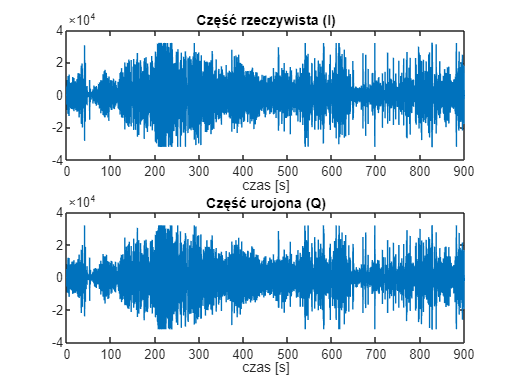

I = signal.table2(1, :);
Q = signal.table2(2, :);
fs = 2000;          %f probkowania
f0 = 2e6;            
t = (0:length(I)-1)/fs;

% decymacja tutaj do 200 Hz
decimation_factor = fs / 200;   % 2000/200 = 10
I_dec = decimate(I, decimation_factor);
Q_dec = decimate(Q, decimation_factor);

fs_dec = fs / decimation_factor;  
t_dec = (0:length(I_dec)-1)/fs_dec;  

%filtracja
f_low = 10;         % dolna granica pasma [Hz]
f_high = 25;        % górna granica pasma [Hz]
order = 4;          %rząd filtru (dopisane 2 zera??) POKOMBINOWAĆ

%rekonstrukcja sygnału
z = I + 1j*Q;

figure;
subplot(2,1,1); plot(t, real(z)); title('Część rzeczywista (I)'); xlabel('czas [s]');
xlim([0 900]);
subplot(2,1,2); plot(t, imag(z)); title('Część urojona (Q)'); xlabel('czas [s]');
xlim([0 900])

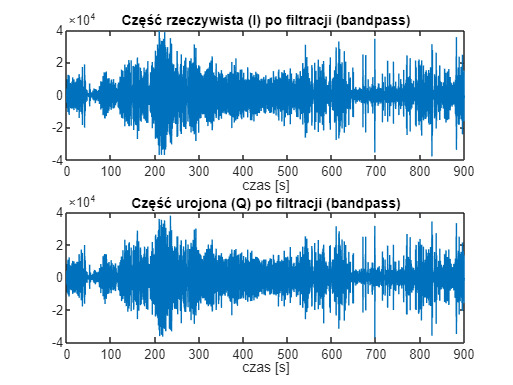


%Wn = [f_low f_high] / (fs/2);    % normowanie częstotliwości
%[b, a] = butter(order, Wn, 'bandpass');
f_low = 10;          % dolna granica pasma [Hz]
f_high = 25;         % górna granica pasma [Hz]

I_filtered = bandpass(I_dec, [f_low f_high], fs_dec);
Q_filtered = bandpass(Q_dec, [f_low f_high], fs_dec);

%I_filtered = filtfilt(b, a, I); %filtracja
%Q_filtered = filtfilt(b, a, Q);

%rekonstrukcja sygnału
z_filtered = I_filtered + 1j*Q_filtered;

%figure;
%subplot(2,1,1); plot(t, real(z_filtered)); title('Część rzeczywista (I) po filtracji'); xlabel('czas [s]');
%xlim([0 900])
%subplot(2,1,2); plot(t, imag(z_filtered)); title('Część urojona (Q) po filtracji'); xlabel('czas [s]');
%xlim([0 900])

figure;
subplot(2,1,1);
plot(t_dec, real(z_filtered));
title('Część rzeczywista (I) po filtracji (bandpass)');
xlabel('czas [s]');
xlim([0 900]);
subplot(2,1,2);
plot(t_dec, imag(z_filtered));
title('Część urojona (Q) po filtracji (bandpass)');
xlabel('czas [s]');
xlim([0 900]);

Wyznaczenie obwiedni (moduł sygnału zespolonego) i spektrogramu sygnału

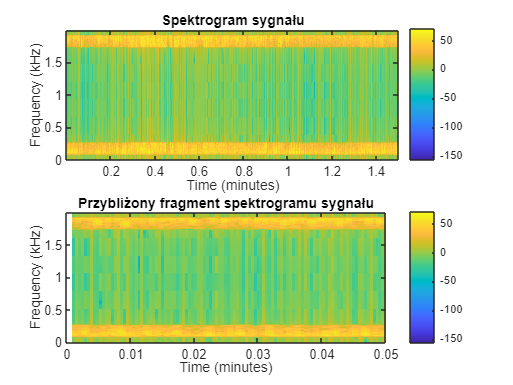

envelope = abs(z);
window = hamming(256); % rozmiar okna
noverlap = 200;        % nakładanie okien
nfft = 512;            % długość FFT
subplot(2,1,1);
spectrogram(z_filtered, window, noverlap, nfft, fs, 'yaxis');
colorbar;
title('Spektrogram sygnału');

subplot(2,1,2);
spectrogram(z_filtered, window, noverlap, nfft, fs, 'yaxis');
colorbar;
xlim([0 0.05]); % 0.05*60sek = 3sekundy
title('Przybliżony fragment spektrogramu sygnału'); % żółty pasek i dalej niebieski powinien być

Wyznaczenie sygnałów kierunkowych i ich obwiedni analitycznych + decymacja do fs=20Hz

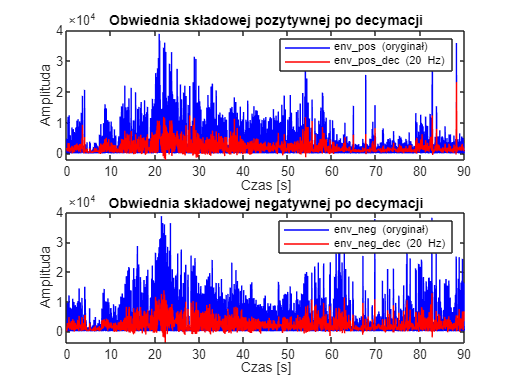

%składowe kierunkowe
% z_filtered = I_filtered + 1j*Q_filtered;
x_pos = (real(z_filtered) + imag(hilbert(imag(z_filtered)))) / 2;   % prędkości do głowicy 
x_neg = (real(z_filtered) - imag(hilbert(imag(z_filtered)))) / 2;   % prędkości od głowicy imag od hilberta od imag od z filtered zamiast real

%wziac jeden syganl kierunkowy, z jednego
%zrobić obwiednię, wybrać jedną z tych niżej i zrobic jego analize widmowa
%(FFT)

%obwiednia analityczna
env_pos = abs(hilbert(x_pos));  % obwiednia składowej pozytywnej (do głowicy) te śą ok
env_neg = abs(hilbert(x_neg));  % obwiednia składowej negatywnej (od głowicy)

%decymacja do 20 Hz bez tego
Fs_new     = 20;                        % docelowa fs
down_factor = round(fs / Fs_new);     
env_pos_dec = decimate(env_pos, down_factor);
env_neg_dec = decimate(env_neg, down_factor);
t_new       = (0:length(env_pos_dec)-1)/Fs_new;

figure;
subplot(2,1,1);
plot((0:length(env_pos)-1)/fs, env_pos, 'b'); hold on;
plot(t_new, env_pos_dec, 'r');
hold off;
legend('env\_pos (oryginał)', 'env\_pos\_dec (20 Hz)');
xlabel('Czas [s]'); ylabel('Amplituda');
title('Obwiednia składowej pozytywnej po decymacji');

subplot(2,1,2);
plot((0:length(env_neg)-1)/fs, env_neg, 'b'); hold on;
plot(t_new, env_neg_dec, 'r');
hold off;
legend('env\_neg (oryginał)', 'env\_neg\_dec (20 Hz)');
xlabel('Czas [s]'); ylabel('Amplituda');
title('Obwiednia składowej negatywnej po decymacji');

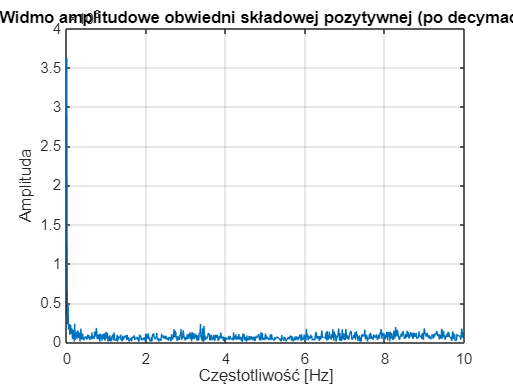



%Analiza widmowa obwiedni pozytywnej po decymacji

N = length(env_pos_dec);    % liczba próbek
Y = fft(env_pos_dec);       % szybka transformata Fouriera
f = (0:N-1)*(Fs_new/N);     % wektor częstotliwości

% Bierzemy tylko pierwszą połowę (symetria widma dla sygnału rzeczywistego)
half_N = floor(N/2);
Y_mag = abs(Y(1:half_N));       % amplituda
f_half = f(1:half_N);            % odpowiadające częstotliwości

figure;
plot(f_half, Y_mag);
xlabel('Częstotliwość [Hz]');
ylabel('Amplituda');
title('Widmo amplitudowe obwiedni składowej pozytywnej (po decymacji)');
grid on;

Analiza widmowa obwiedni sygnału kierunkowego (5s, długość ciągu poddawanego transformacie fouriera =1024)

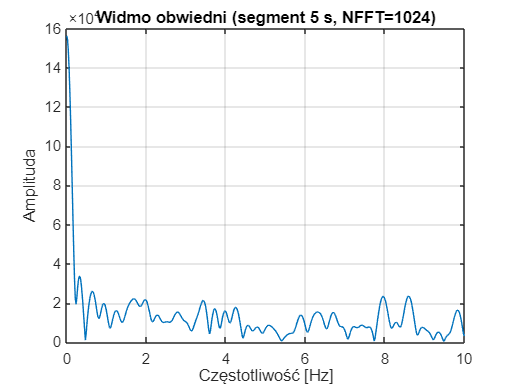

segment = 5;         % długość okna w sekundach
nfft = 1024;       % długość transformacji Fouriera

%analiza do głowicy
env = env_pos_dec;    %ewentualnie od głowicy: env_neg_dec

%wycięcie fragmentu 5 sek:
Nseg = segment * Fs_new;         % liczba próbek w segmencie
if length(env) < Nseg
    error('Obwiedź ma mniej niż %d próbek!', Nseg);
end
x_seg = env(1:Nseg);

%FFT
X = fft(x_seg, nfft);
X_mag = abs(X(1:nfft/2+1));          % jedynie połowa symetryczna
f = (0:(nfft/2)) * (Fs_new/nfft);    % wektor częstotliwości [Hz]

%widmo amplitudowe
%można dodać dla kierunku OD głowicy
figure;
plot(f, X_mag);
xlabel('Częstotliwość [Hz]');
ylabel('Amplituda');
title(sprintf('Widmo obwiedni (segment %d s, NFFT=%d)', segment, nfft));
xlim([0 Fs_new/2]);
grid on;

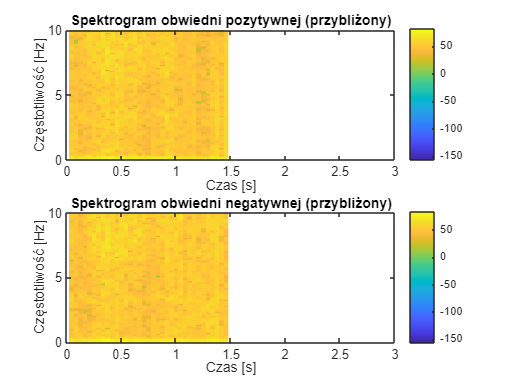


%spektrogram
win_lenght = segment*Fs_new;
window = hamming(win_lenght);
noverlap = round(0.5*win_lenght); %50% nakładania
figure;
subplot(2,1,1);
spectrogram(env_pos_dec, window, noverlap, nfft, Fs_new, 'yaxis');
title('Spektrogram obwiedni pozytywnej (przybliżony)');
xlim([0 3]);
xlabel('Czas [s]');
ylabel('Częstotliwość [Hz]');
colorbar;

subplot(2,1,2);
spectrogram(env_neg_dec, window, noverlap, nfft, Fs_new, 'yaxis');
title('Spektrogram obwiedni negatywnej (przybliżony)');
xlim([0 3]);
xlabel('Czas [s]');
ylabel('Częstotliwość [Hz]');
colorbar;

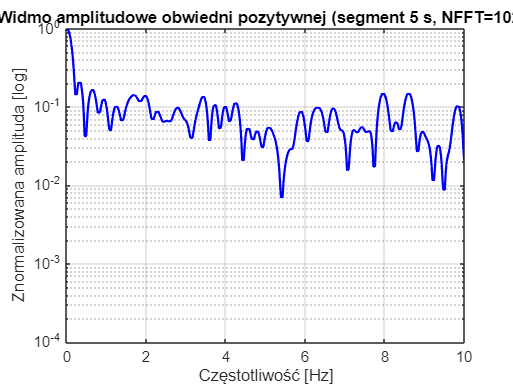

% Parametry
segment = 5;         % długość wycinka [s]
nfft = 1024;         % liczba punktów FFT
Fs_new = 20;         % częstotliwość po decymacji

% Obwiednia pozytywna
env = env_pos_dec;

% Wycięcie 5s fragmentu
Nseg = segment * Fs_new;         % liczba próbek w segmencie
if length(env) < Nseg
    error('Obwiednia ma mniej niż %d próbek!', Nseg);
end
x_seg = env(1:Nseg);

% FFT
X = fft(x_seg, nfft);
X_mag = abs(X(1:nfft/2+1));          % widmo amplitudowe (połówka)
X_mag = X_mag / max(X_mag);           % normalizacja do 1 (opcjonalnie)

f = (0:(nfft/2)) * (Fs_new/nfft);     % wektor częstotliwości [Hz]

% Opcjonalne wygładzenie (np. filtr medianowy)
X_mag_smooth = medfilt1(X_mag, 5);    % filtr medianowy z oknem 5 punktów

% Widmo amplitudowe
figure;
semilogy(f, X_mag_smooth, 'b', 'LineWidth', 1.5); grid on;
xlabel('Częstotliwość [Hz]');
ylabel('Znormalizowana amplituda [log]');
title(sprintf('Widmo amplitudowe obwiedni pozytywnej (segment %d s, NFFT=%d)', segment, nfft));
xlim([0 Fs_new/2]);
ylim([1e-4 1]);    % lepszy zakres amplitudy

Wykres przemieszczenia

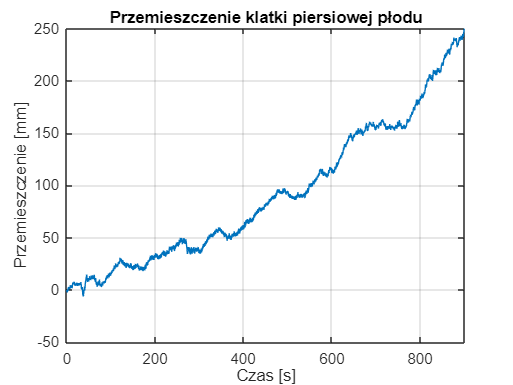

%faza sygnału analitycznego
phi = unwrap(angle(z_filtered));  % Odwijanie fazy

%z dopplera (wzór z książki):
% d(t) = (c / (4 * pi * f0)) * phi(t)
c = 1540;  %prędkość dźwięku w tkance miękkiej
d = (c / (4 * pi * f0)) * phi;

% analiza widmowa przemieszczen!

%wykres przemieszczenia
figure;
plot(t_dec, d * 1000); % w mm
xlabel('Czas [s]');
ylabel('Przemieszczenie [mm]');
title('Przemieszczenie klatki piersiowej płodu');
xlim([0 max(t)]);
grid on;

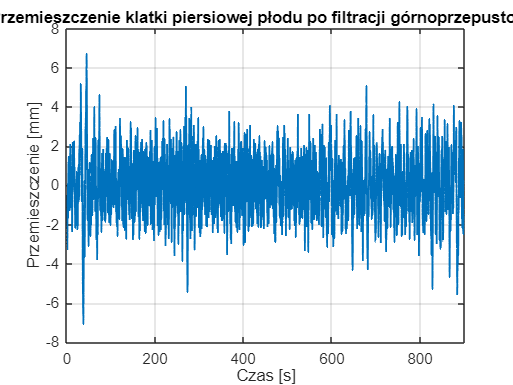


% --- Załóżmy, że:
% d     – sygnał przemieszczenia po analizie fazy i decymacji do 200 Hz
% Fs1   – częstotliwość próbkowania po pierwszej decymacji, czyli 200 Hz
Fs1 = 200; %[Hz]

% Parametry drugiej decymacji:
decFact = 10;           % chcemy zejść z 200 Hz do 20 Hz
Fs2     = Fs1/decFact;  % = 20 Hz

% 1) Decymacja
d_dec = decimate(d, decFact);

% 2) Budowa wektora czasu
t2 = (0:length(d_dec)-1)/Fs2;

% 3) Filtr górnoprzepustowy
%    - usuwamy trend poniżej ~0.05 Hz (ruch oddechowy 0.2–0.5 Hz zostaje)
Fc     = 0.05;                   % Hz
[b_hp, a_hp] = butter(4, Fc/(Fs2/2), 'high');
d_filt = filtfilt(b_hp, a_hp, d_dec);

% 4.1 Wykres przemieszczenia po filtracji
figure;
plot(t2, d_filt*1000, 'LineWidth', 1.2);
xlabel('Czas [s]');
ylabel('Przemieszczenie [mm]');
title('Przemieszczenie klatki piersiowej płodu po filtracji górnoprzepustowej');
xlim([0 max(t2)]);
grid on;

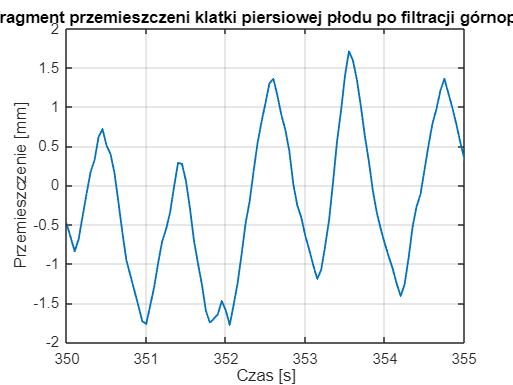


% 4.2 Wykres przemieszczenia po filtracji
figure;
plot(t2, d_filt*1000, 'LineWidth', 1.2);
xlabel('Czas [s]');
ylabel('Przemieszczenie [mm]');
title('Wybrany fragment przemieszczeni klatki piersiowej płodu po filtracji górnoprzepustowej');
xlim([350 355]);
grid on;

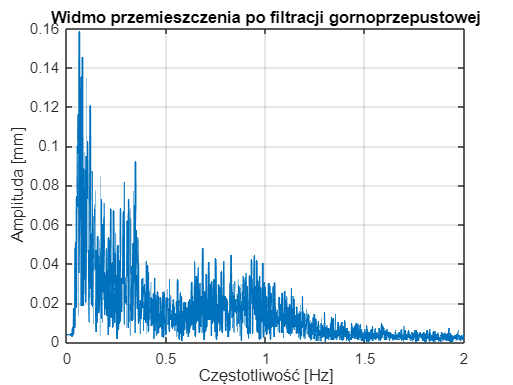


% 5) Analiza widmowa (FFT)
N     = length(d_filt);
Y     = fft(d_filt);
Y_mag = abs(Y(1:floor(N/2)+1))/N;       % znormalizowana amplituda
f_vec = (0:floor(N/2))*(Fs2/N);         % wektor częstotliwości

figure;
plot(f_vec, Y_mag*1000, 'LineWidth', 1.2);
xlabel('Częstotliwość [Hz]');
ylabel('Amplituda [mm]');
title('Widmo przemieszczenia po filtracji gornoprzepustowej');
xlim([0 2]);    % interesujący zakres do ~2 Hz
grid on;

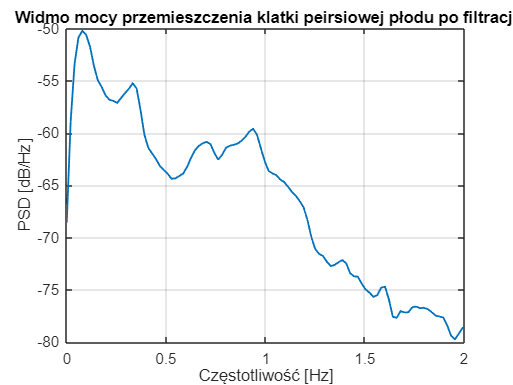


% 6) Analiza widmowa mocy sygnału przemieszczenia
% Parametry do pwelch:
Fs2        = 20;        % częstotliwość próbkowania sygnału po decymacji
window_sec = 60;        % długość okna w sekundach (np. 60 s by mieć resolucję ~0.017 Hz)
%window     = window_sec * Fs2;
%noverlap   = round(0.5*window);  % 50% nakładania
%nfft       = max(2^nextpow2(window), 1024);  % FFT co najmniej 1024 punktów

window = 512; 
noverlap = window/4;
nfft = window *2;

% Estymacja PSD:
[PSD, f_psd] = pwelch(d_filt, window, noverlap, nfft, Fs2);

% Rysunek:
figure;
plot(f_psd, 10*log10(PSD), 'LineWidth', 1.2);
xlabel('Częstotliwość [Hz]');
ylabel('PSD [dB/Hz]');
title('Widmo mocy przemieszczenia klatki peirsiowej płodu po filtracji');
xlim([0 2]);  % interesuje nas zakres do ~2 Hz
grid on;


% automatyczne wykrycia piku oddechowego
f_min = 0.2;
f_max = 1.0;
idx   = f>=f_min & f<=f_max;
[~, imax] = max(PSD(idx));
f_breath = f(idx);
f_breath = f_breath(imax);
fprintf('Oddechy: %.2f Hz (≈ %.1f oddechów/min)\n', f_breath, f_breath*60);

Oddechy: 0.33 Hz (≈ 19.9 oddechów/min)
